## **Chapter 4**

format compact
close all
clear
clc

### 4.1.1 Car-like mobile robots

sl_lanechange
% we can't push the simulate button on the Simulink model from this script so we simulate it
out = sim('sl_lanechange')

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


out

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


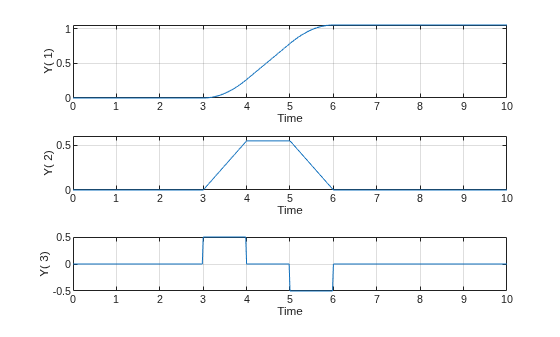

t = out.get('t'); q = out.get('y');

figure
mplot(t, q(:,2:4))

q

q =          0         0         0         0
    0.0002         0         0         0
    0.0012         0         0         0
    0.0062         0         0         0
    0.0200         0         0         0
    0.0400         0         0         0
    0.0600         0         0         0
    0.0800         0         0         0
    0.1000         0         0         0
    0.1200         0         0         0
    0.1400         0         0         0
    0.1600         0         0         0
    0.1800         0         0         0
    0.2000         0         0         0
    0.2200         0         0         0


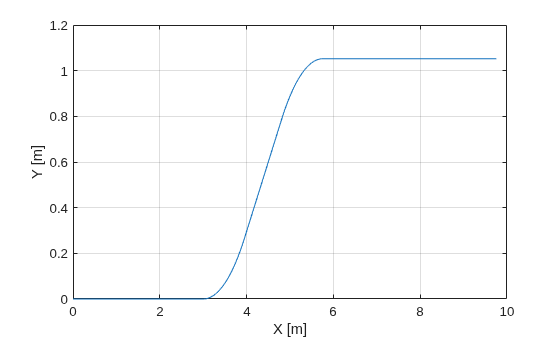

clf
plot(q(:,1), q(:,2))
grid on, xlabel('X [m]'), ylabel('Y [m]')

### 4.1.1.1 Moving to a point

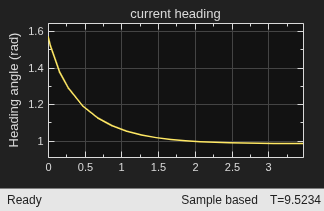

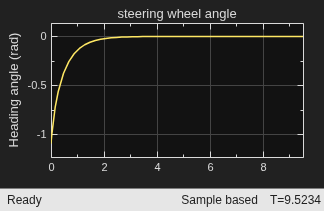

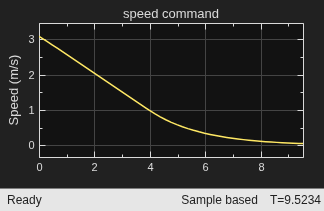

bdclose('all');
clf

sl_drivepoint

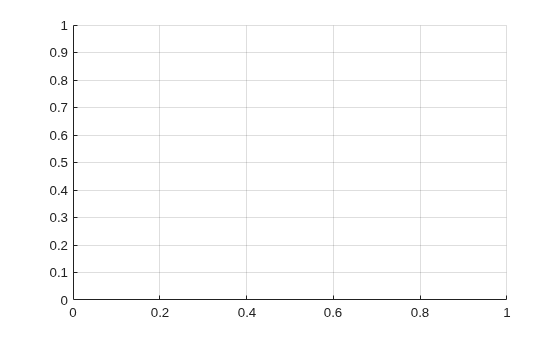


xg = [3 5];

x0 = [0 0 pi/2];

r = sim('sl_drivepoint');
grid on
hold on

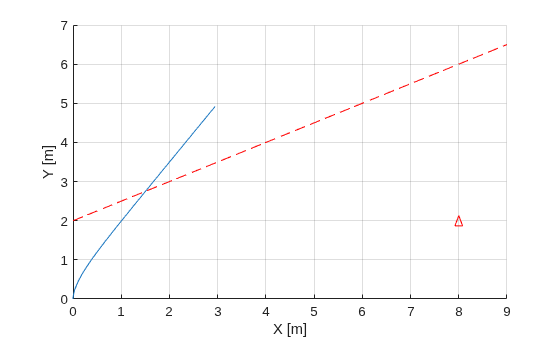

q = r.find('y');
hold on
plot(q(:,1), q(:,2));
grid on, xlabel('X [m]'), ylabel('Y [m]')

### 4.1.1.2 Following a line

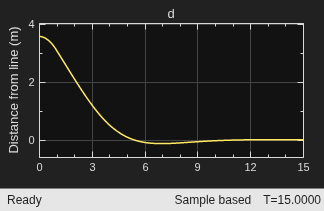

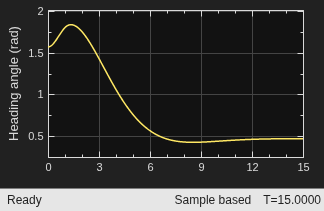

bdclose('all');
clf

sl_driveline

L = [1 -2 4];

x0 = [8 2 pi/2];

r = sim('sl_driveline');

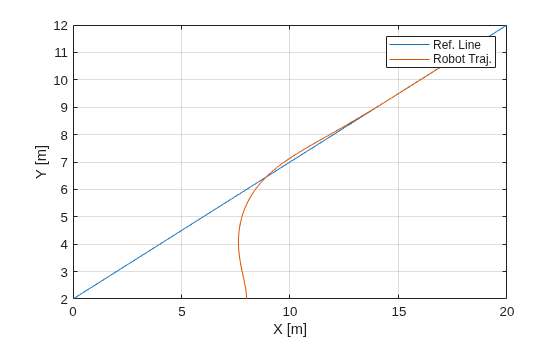

clf
x = 0:0.01:20;
% refline([1/2 2])
grid on 
box on
hold on
y = (-L(1)*x - L(3))/L(2);
plot(x,y)
hold on
plot(r.y(:,1),r.y(:,2))
legend('Ref. Line', 'Robot Traj.'), xlabel('X [m]'), ylabel('Y [m]')

### 4.1.1.3 Following a trajectory

bdclose('all');
clf
% sl_pursuit

currDir = '/home/juulg/Documents/MATLAB/R7010E/Lectures/Lecture4Simulink';
[currDir './sl_pursuit']

ans = '/home/juulg/Documents/MATLAB/R7010E/Lectures/Lecture4Simulink./sl_pursuit'

r = sim(join([currDir '/sl_pursuitMarios.slx']))

Model '/home/juulg/Documents/MATLAB/R7010E/Lectures/Lecture4Simulink/sl_pursuitMarios.slx' does not exist.

r.y

figure
plot(r.y(:,1),r.y(:,2))
hold on
plot(r.y(:,3),r.y(:,4))
legend('Robot Traj.','Ref. Line'), xlabel('X [m]'), ylabel('Y [m]')

### 4.1.1.4  Moving to a pose

bdclose('all');
clf

sl_drivepose

xg = [5 5 pi/2];

x0 = [9 5 0];

r = sim('sl_drivepose');

q = r.find('y');
clf
plot(q(:,1), q(:,2));
hold on
 grid on
xlim([4 10])
ylim([4 6])

R0 = rot2(x0(3)); Rg = rot2(xg(3));
x01 = R0 * [0.6 0]';
xg1 = Rg * [0.6 0]';

quiver(xg(1),xg(2), xg1(1),xg1(2),'LineWidth',1)
quiver(x0(1),x0(2), x01(1),x01(2),'LineWidth',1)
legend('Robot Traj.'), xlabel('X [m]'), ylabel('Y [m]')